clc; clear; close all; 
addpath('functions/');

n = 200;
x1 = 5;
v1 = 1;
t = 1;
sigmaA = 0.2;
sigmaN = 20;

G = [(t^2)/2; t];
F = [1, t; 0, 1];
H = [1, 0];

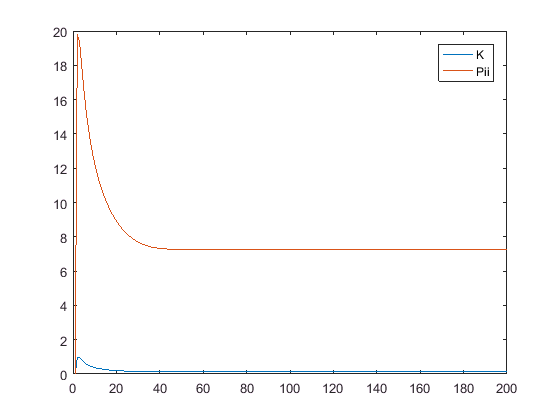

% [ X, Z, a, Noise ] = randomAcceleration( n, sigmaA, sigmaN, x1, v1, t); 
% [ X, Z, a, Noise ] = rndAccStateSpace( n, sigmaA, sigmaN, x1, v1, t, F, G, H); 

a = normrnd(0,sigmaA,1,n);
Noise = normrnd(0,sigmaN,1,n);

G = [(t^2)/2; t];
F = [1, t; 0, 1];
H = [1, 0];

X = zeros(2, n);
Z = zeros(1, n);
X(:, 1) = [x1; v1];

for i=2:n
    X(:, i) = F*X(:,i-1) + G*a(i);
    Z(i) = H*X(:,i) + Noise(i); 
end

Xk = zeros(2, n);
Xk(:, 1) = [x1; v1];

Q=sigmaA^2 * (G*G');
P=[10000, 0; 0, 10000];

for i=2:n
    P=F*P*F'+Q;
    K=P*H'/(H*P*H'+ sigmaN^2);
    Xk(:,i) = F*Xk(:, i-1);
    Xk(:,i) = Xk(:,i)+K*(Z(i)-H*Xk(:,i));
    
    P=(eye(2)-K*H)*P;
    Kplot(:,i)=K;
    Pplot(i)=sqrt(P(1,1));
end
plot(Kplot(1,:));
hold on;
plot(Pplot);
legend('K','Pii')

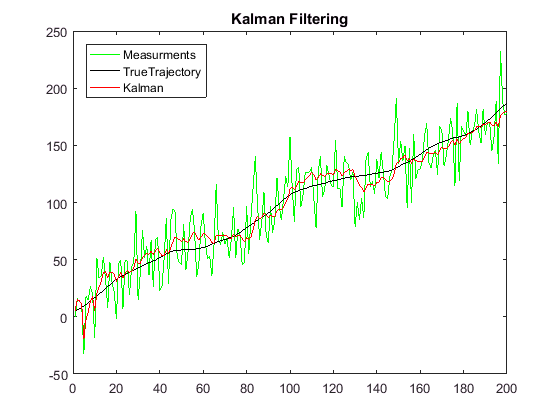


figure;
plot (Z,'green')
hold on;
plot (X(1,:),'black');
plot (Xk(1,:),'red');
legend('Measurments','TrueTrajectory','Kalman','Location','northwest');
title('Kalman Filtering');

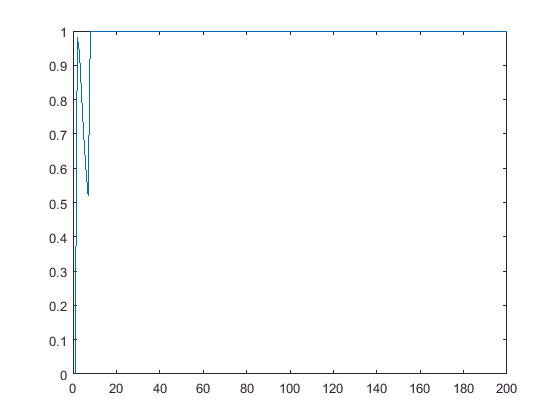

%%%%%%point №7
M=100;
ErrSum=zeros(1,n);

for i=1:M
    
            a = normrnd(0,sigmaA,1,n);
        Noise = normrnd(0,sigmaN,1,n);


           X = zeros(2, n);
           Z = zeros(1, n);
           X(:, 1) = [x1; v1];

            for i=2:n
                X(:, i) = F*X(:,i-1) + G*a(i);
                Z(i) = H*X(:,i) + Noise(i); 
            end

    
            Xk = zeros(2, n);
            for i =1:7
            Xk(:, i) = [X(1,i); X(2,i)];
            end
    
    Q=sigmaA^2 * (G*G');
    P=[10000, 0; 0, 10000];
    F=F*F*F*F*F*F;
    
    for i=8:n
        P=F*P*F'+Q;
        K=P*H'/(H*P*H'+ sigmaN^2);
        Xk(:,i) = F*Xk(:, i-7);
        Xk(:,i) = Xk(:,i)+K*(Z(i)-H*Xk(:,i));
        
        P=(eye(2)-K*H)*P;
        Kplot(:,i)=K;
        Pplot(i)=sqrt(P(1,1));
    end
    ErrCur = ( X(1,:) - Xk(1,:) ).^2;
    ErrSum = ErrSum + ErrCur;
end
FinalError = ( ErrSum(3:end)./(M-1) ).^0.5;

figure
plot(Kplot(1,:));

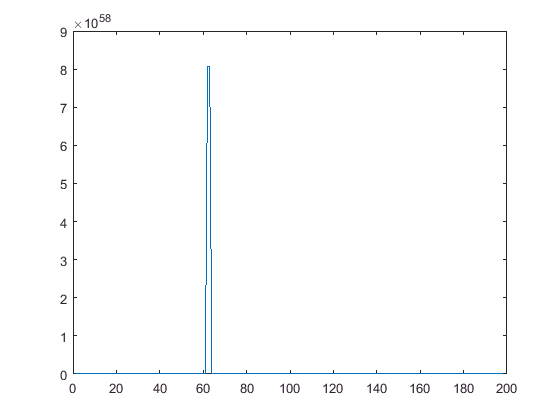

figure
plot(FinalError);

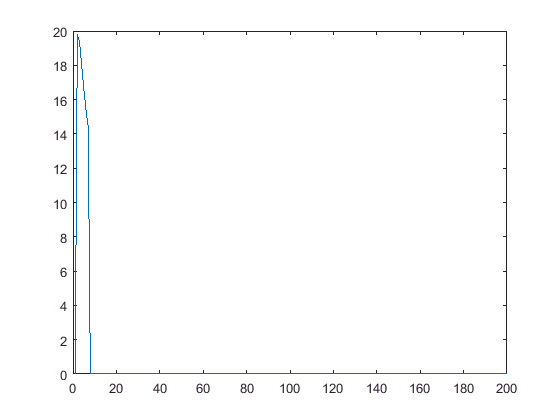

figure
plot(Pplot)